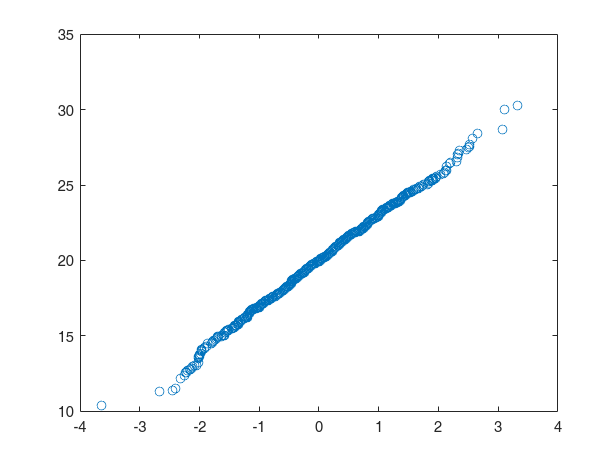

n = 1000;
X = 20 +3*randn(n,1);
XOrd = sort(X);
Z = randn(n,1);
ZOrd = sort(Z); 

plot (ZOrd,XOrd,'o') %se deberia ver una linea recta

fitlm(ZOrd,XOrd) %regresion lineal de los datos ordenados

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat     pValue
                   ________    _________    ______    ______

    (Intercept)     19.969     0.0046535    4291.1      0   
    x1               3.039     0.0047434    640.68      0   


Number of observations: 1000, Error degrees of freedom: 998
Root Mean Squared Error: 0.147
R-squared: 0.998,  Adjusted R-Squared: 0.998
F-statistic vs. constant model: 4.1e+05, p-value = 0

%Para ver si es normal miramos el ajust(R-squared)
%Hipotesis nula: todos los betas son 0 (No hay modelo)
%Pvalue<0.05, rechazamos. E.O.C no hay suficiente evidencia

Para estimar Beta se hace a traves de ${\left(X^{\prime } X\right)}^{-1} X^{\prime } Y$ pero como para esto no es muy facil de asegurar que esta bien condicionado la matriz X'X por lo que para acondicionarla se le añade un lambda a la diagonal para aumentar el valor de la determinante y asi asegurar que quede bien condicionada ${\left(X^{\prime } X+\lambda I\right)}^{-1} X^{\prime } Y$. A esto se le llama Ridge Regression.

Pero ya no se puede calcular Beta de la misma manera que se calculaba pues cambio la formula. Por tanto se le hace un bootstrap para calcular el intervalo de confianza 

betaEst = inv(X'*X)*X'*Z

betaEst = -2.0743e-04